## Optimization

clc;
clear all;
close all;

p_load = xlsread('Data analysis.xlsx','Analysis','C2:C8761');
f_pv = xlsread('Data analysis.xlsx','Analysis','H2:H8761');
f_wind = xlsread('Data analysis.xlsx', 'Analysis','E2:E8761');

%x = [Pnuc Psolar Pwind Pgas Psolar1 ... Psolar8760 Pwind1 ... Pwind8760 Pgas1 ... Pgas8760]

years = 25;

% Minimum renewable energy percentage in one year
p = 1;
total_demand = sum(p_load);

% Objective Function

CAPEXnuc = 5700e3; % € per MW
OPEXnuc = 30.5; % € per MWh

CAPEXsolar = 800e3; % € per MW
OPEXsolar = 17e3; % € per MW per year

CAPEXwind = 1350e3; % € per MW
OPEXwind = 90e3; % € per MW per year

CAPEXgas = 696e3; % € per MW
OPEXgas = 199; % € per MWh

f(1) = CAPEXnuc + OPEXnuc*8760*years;

f(2) = CAPEXsolar;

f(3) = CAPEXwind;

f(4) = CAPEXgas;

f(5:8764) = (OPEXsolar*years);

f(8765:17524) = (OPEXwind*years);

f(17525:26284) = (OPEXgas*8760*years);

% Inequality Constraints for solar, wind, and gas
A = zeros(4 * 8761, 26284); % Adjusted size to accommodate new constraints
b = zeros(4 * 8761, 1);     % Adjusted size to accommodate new constraints

% Annual renewable energy constraint
A_renewable = zeros(1, 26284);
A_renewable(5:8764) = -1;          % Solar contribution
A_renewable(8765:17524) = -1;      % Wind contribution
b_renewable = -p * total_demand;   % Total renewables ≥ x% of total demand

A = [A; A_renewable];
b = [b; b_renewable];

% Total generation is equal too demand

Aeq(1:8760,1) = 1;
Aeq(1:8760,2) = 0;
Aeq(1:8760,3) = 0;
Aeq(1:8760,4) = 0;
Aeq(1:8760,5:8764) = eye(8760);
Aeq(1:8760,8765:17524) = eye(8760);
Aeq(1:8760,17525:26284) = eye(8760);

beq = p_load;

% Renewable constraint: Solar + Wind >= x% of annual demand

A(3*8760+1:4*8760, 5:8764) = -eye(8760);            % Solar contribution
A(3*8760+1:4*8760, 8765:17524) = -eye(8760);        % Wind contribution
A(3*8760+1:4*8760, 1) = (p - 1) * ones(8760, 1);    % Adjust nuclear base load to compensate
b(3*8760+1:4*8760) = -(p * p_load);                 % Demand multiplied by x%


% Solar power hourly is <= Predicted solar power hourly 
% and Wind power hourly is <= Predicted wind power hourly
% and Gas power hourly is <= Nominal gas power

A(1:3*8760,1) = 0;

A(1:8760,2) = -f_pv;
A(8761:3*8760,2) = 0;

A(1:8760,3) = 0;
A(8761:2*8760,3) = -f_wind;
A(17521:3*8760,3) = 0;

A(1:2*8760,4) = 0;
A(17521:3*8760,4) = -1;

A(1:8760,5:8764) = eye(8760);
A(8761:3*8760,5:8764) = 0;

A(1:8760,8765:17524) = 0;
A(8761:2*8760,8765:17524) = eye(8760);
A(17521:3*8760,8765:17524) = 0;

A(1:2*8760,17525:26284) = 0;
A(17521:3*8760,17525:26284) = eye(8760);


b(1:3*8760) = 0;

lb(1:1:26284) = 0;
ub(1:1:26284) = inf;

[x,fval] = linprog(f,A,b,Aeq,beq,lb,ub);


Optimal solution found.



## Results


p_nuc(1:8760) = x(1);
p_solar(1:8760) = x(5:8764);
p_wind(1:8760) = x(8765:17524);
p_gas(1:8760) = x(17525:26284);

p_nom_nuc = x(1);
p_nom_solar = x(2);
p_nom_wind = x(3);
p_nom_gas = x(4);
p_nom_renewable = p_nom_solar + p_nom_wind;

% Calculate total renewable fraction
total_solar_energy = sum(p_solar); % Total solar energy over the year
total_wind_energy = sum(p_wind);  % Total wind energy over the year
total_renewable_energy = total_solar_energy + total_wind_energy;
renewable_fraction = total_renewable_energy / total_demand;

% Calculate CAPEX for each power source
CAPEX_nuc_total = p_nom_nuc * CAPEXnuc;  
CAPEX_solar_total = p_nom_solar * CAPEXsolar;  
CAPEX_wind_total = p_nom_wind * CAPEXwind;    
CAPEX_gas_total = p_nom_gas * CAPEXgas;      

% Calculate OPEX for each power source (annual OPEX multiplied by years)
OPEX_nuc_total = p_nom_nuc * OPEXnuc;
OPEX_solar_total = p_nom_solar * OPEXsolar;
OPEX_wind_total = p_nom_wind * OPEXwind;
OPEX_gas_total = p_nom_gas * OPEXgas;

% Total CAPEX and OPEX for all power sources
total_CAPEX = CAPEX_nuc_total + CAPEX_solar_total + CAPEX_wind_total + CAPEX_gas_total;
total_OPEX = OPEX_nuc_total + OPEX_solar_total + OPEX_wind_total + OPEX_gas_total;

% Display results
disp(['Total fraction of demand covered by renewables: ', num2str(renewable_fraction * 100), '%']);

Total fraction of demand covered by renewables: 100%



fprintf('The nominal power of installed nuclear is : %d MW\n', p_nom_nuc);

The nominal power of installed nuclear is : 0 MW


fprintf('The nominal power of installed solar is : %d MW\n', p_nom_solar);

The nominal power of installed solar is : 1.279367e+07 MW


fprintf('The nominal power of installed wind is : %d MW\n', p_nom_wind);

The nominal power of installed wind is : 2127875 MW


fprintf('The nominal power of installed gas is : %d MW\n', p_nom_gas);

The nominal power of installed gas is : 0 MW



fprintf('Total CAPEX (Nuclear): €%.2f\n', CAPEX_nuc_total);

Total CAPEX (Nuclear): €-0.00


fprintf('Total CAPEX (Solar): €%.2f\n', CAPEX_solar_total);

Total CAPEX (Solar): €10234933333333.33


fprintf('Total CAPEX (Wind): €%.2f\n', CAPEX_wind_total);

Total CAPEX (Wind): €2872631250000.00


fprintf('Total CAPEX (Gas): €%.2f\n', CAPEX_gas_total);

Total CAPEX (Gas): €0.00


fprintf('Total OPEX (Nuclear): €%.2f\n', OPEX_nuc_total);

Total OPEX (Nuclear): €-0.00


fprintf('Total OPEX (Solar): €%.2f\n', OPEX_solar_total);

Total OPEX (Solar): €217492333333.33


fprintf('Total OPEX (Wind): €%.2f\n', OPEX_wind_total);

Total OPEX (Wind): €191508750000.00


fprintf('Total OPEX (Gas): €%.2f\n', OPEX_gas_total);

Total OPEX (Gas): €0.00


fprintf('Total CAPEX for all sources is; billion €%.2f', total_CAPEX/1000000000);

Total CAPEX for all sources is; billion €13107.56

fprintf('Total OPEX for all sources is: billion €%.2f\n', total_OPEX/1000000000);

Total OPEX for all sources is: billion €409.00


## Plot

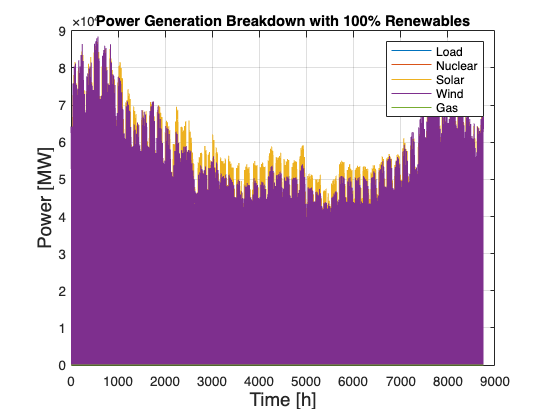

h = (1:1:8760);
p = p *100;

figure;
plot(h,p_load,h,p_nuc,h,p_solar,h,p_wind,h,p_gas);
grid on;
legend('Load','Nuclear','Solar','Wind','Gas');   
xlabel('Time [h]','FontSize',14);
ylabel('Power [MW]','FontSize',14);
title("Power Generation Breakdown with " + p + "% Renewables");

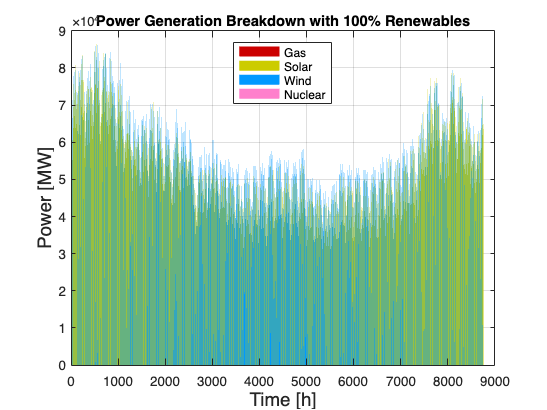



% Plot stacked area chart
h = 1:8760;
p_nuc = x(1) * ones(8760, 1);       % Nuclear power
p_solar = x(5:8764);                % Solar power
p_wind = x(8765:17524);             % Wind power
p_gas = x(17525:26284);             % Gas power

area(h, [p_nuc, p_solar, p_wind, p_gas], 'LineStyle', 'none');
grid on;

% Customizing the colors
h_areas = gca().Children;
h_areas(1).FaceColor = [0.8, 0, 0];  % Nuclear -> pink
h_areas(2).FaceColor = [0.8, 0.8, 0];    % Solar -> yellow
h_areas(3).FaceColor = [0, 0.6, 1];      % Wind -> blue
h_areas(4).FaceColor = [1, 0.5, 0.8];      % Gas -> red

% plot(h, p_load, 'k', 'LineWidth', 0.5); 

legend('Nuclear', 'Wind', 'Solar', 'Gas', 'Location', 'Best');
xlabel('Time [h]', 'FontSize', 14);
ylabel('Power [MW]', 'FontSize', 14);
title("Power Generation Breakdown with " + p + "% Renewables");


% STACKED GRAPH VERSION 1

% % Ensure the data arrays are column vectors for consistent concatenation
% h = (1:8760)'; % Ensure time is a column vector
% p_nuc = p_nuc(:); % Convert to column vector
% p_solar = p_solar(:); % Convert to column vector
% p_wind = p_wind(:); % Convert to column vector
% p_gas = p_gas(:); % Convert to column vector
% p_load = p_load(:); % Convert to column vector
% 
% % Cumulative contributions for stacking
% p_cumulative_nuc = p_nuc;                        % Nuclear is the base layer
% p_cumulative_solar = p_cumulative_nuc + p_solar; % Add solar to nuclear
% p_cumulative_wind = p_cumulative_solar + p_wind; % Add wind to solar
% p_cumulative_gas = p_cumulative_wind + p_gas;    % Add gas to wind
% 
% % Plot
% figure;
% hold on;
% fill([h; flipud(h)], [zeros(size(h)); flipud(p_cumulative_nuc)], 'b', ...
%     'FaceAlpha', 0.5, 'EdgeColor', 'none');
% fill([h; flipud(h)], [p_cumulative_nuc; flipud(p_cumulative_solar)], 'y', ...
%     'FaceAlpha', 0.5, 'EdgeColor', 'none');
% fill([h; flipud(h)], [p_cumulative_solar; flipud(p_cumulative_wind)], 'g', ...
%     'FaceAlpha', 0.5, 'EdgeColor', 'none');
% fill([h; flipud(h)], [p_cumulative_wind; flipud(p_cumulative_gas)], 'r', ...
%     'FaceAlpha', 0.5, 'EdgeColor', 'none');

% Overlay demand as a line
% plot(h, p_load, 'k', 'LineWidth', 0.005); % Demand line

% Formatting
% grid on;
% legend('Nuclear', 'Solar', 'Wind', 'Gas', 'Demand', 'Location', 'Best');
% xlabel('Time [h]', 'FontSize', 14);
% ylabel('Power [MW]', 'FontSize', 14);
% title('Stacked Area Chart of Power Supply');
% hold off;